% Locate the TVALID and TLAST control signals of the FFT
fft_out_tvalid = out.TVALID

fft_out_tvalid =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


find(fft_out_tvalid == 1, 1)

ans = 4232

fft_out_tlast = out.TLAST

fft_out_tlast =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


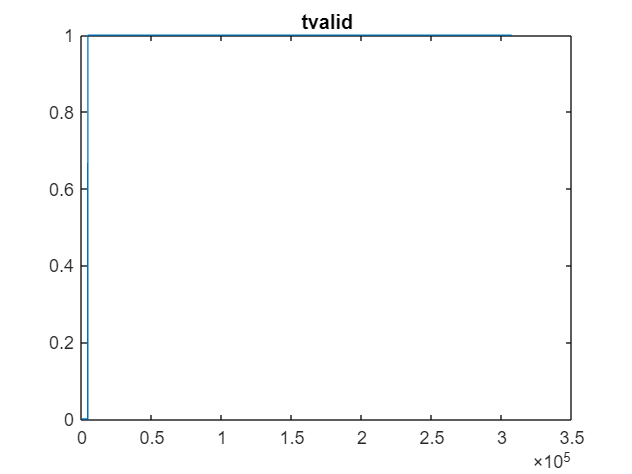

plot(1:length(fft_out_tvalid),fft_out_tvalid)
title('tvalid')

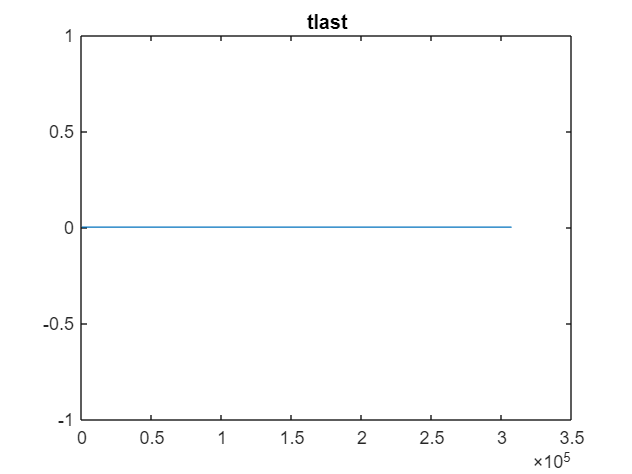

plot(1:length(fft_out_tlast),fft_out_tlast)
title('tlast')


% Locate the FFT data output
fft_out_log_ = out.FFT_out_log

fft_out_log_ =   -Inf
  -Inf
  -Inf
  -Inf
  -Inf
  -Inf
  -Inf
  -Inf
  -Inf
  -Inf


% Only keep the valid samples
fft_out_log = fft_out_log_(find(fft_out_tvalid == 1, 1):end)

fft_out_log =  -109.1212
 -108.9858
 -108.8481
 -108.6073
 -108.4710
 -108.4710
 -108.3327
 -107.9648
 -107.7391
 -107.6041


% Zero-pad if neccessary to ensure # samples is an integer multiple of the
% window size (required for easier spectrogram plotting)
fft_length_before_zero_padding = (ceil(length(fft_out_log)/N))

fft_length_before_zero_padding = 148


% Set the zero-padded values to the minimum value of the valid samples
fft_out_log(length(fft_out_log)+1:fft_length_before_zero_padding*N)=min(fft_out_log)

fft_out_log =  -109.1212
 -108.9858
 -108.8481
 -108.6073
 -108.4710
 -108.4710
 -108.3327
 -107.9648
 -107.7391
 -107.6041



% Determine key parameters
Total_Num_Samples = length(fft_out_log)

Total_Num_Samples = 303104

Num_Segments = Total_Num_Samples/N

Num_Segments = 148


% Create the frequency and time axis for both spectrograms
f_axis_1N = (n/N*fs)/1e6; % From 0 -> fs
f_axis_1N_ = (-N/2:N/2-1)*(fs/N)/1e6; % From -fs/2 -> fs/2 (combined with fftshift for centring DC - as high f is just a spectral replication of -ve f)
t_axis_1N = linspace(0,Total_Num_Samples/fs,Num_Segments)

t_axis_1N = 1.0e-03 *

         0    0.0017    0.0034    0.0050    0.0067    0.0084    0.0101    0.0117    0.0134    0.0151    0.0168    0.0185    0.0201    0.0218    0.0235    0.0252    0.0268    0.0285    0.0302    0.0319    0.0336    0.0352    0.0369    0.0386    0.0403    0.0420    0.0436    0.0453    0.0470    0.0487    0.0503    0.0520    0.0537    0.0554    0.0571    0.0587    0.0604    0.0621    0.0638    0.0654    0.0671    0.0688    0.0705    0.0722    0.0738    0.0755    0.0772    0.0789    0.0805    0.0822


t_axis_1N = 1e3.*t_axis_1N

t_axis_1N =          0    0.0017    0.0034    0.0050    0.0067    0.0084    0.0101    0.0117    0.0134    0.0151    0.0168    0.0185    0.0201    0.0218    0.0235    0.0252    0.0268    0.0285    0.0302    0.0319    0.0336    0.0352    0.0369    0.0386    0.0403    0.0420    0.0436    0.0453    0.0470    0.0487    0.0503    0.0520    0.0537    0.0554    0.0571    0.0587    0.0604    0.0621    0.0638    0.0654    0.0671    0.0688    0.0705    0.0722    0.0738    0.0755    0.0772    0.0789    0.0805    0.0822


f_axis = repmat(f_axis_1N,1,Num_Segments)

f_axis = 1.0e+03 *

         0    0.0006    0.0012    0.0018    0.0024    0.0030    0.0036    0.0042    0.0048    0.0054    0.0060    0.0066    0.0072    0.0078    0.0084    0.0090    0.0096    0.0102    0.0108    0.0114    0.0120    0.0126    0.0132    0.0138    0.0144    0.0150    0.0156    0.0162    0.0168    0.0174    0.0180    0.0186    0.0192    0.0198    0.0204    0.0210    0.0216    0.0222    0.0228    0.0234    0.0240    0.0246    0.0252    0.0258    0.0264    0.0270    0.0276    0.0282    0.0288    0.0294


f_axis_ = repmat(f_axis_1N_,1,Num_Segments)

f_axis_ =  -614.4000 -613.8000 -613.2000 -612.6000 -612.0000 -611.4000 -610.8000 -610.2000 -609.6000 -609.0000 -608.4000 -607.8000 -607.2000 -606.6000 -606.0000 -605.4000 -604.8000 -604.2000 -603.6000 -603.0000 -602.4000 -601.8000 -601.2000 -600.6000 -600.0000 -599.4000 -598.8000 -598.2000 -597.6000 -597.0000 -596.4000 -595.8000 -595.2000 -594.6000 -594.0000 -593.4000 -592.8000 -592.2000 -591.6000 -591.0000 -590.4000 -589.8000 -589.2000 -588.6000 -588.0000 -587.4000 -586.8000 -586.2000 -585.6000 -585.0000


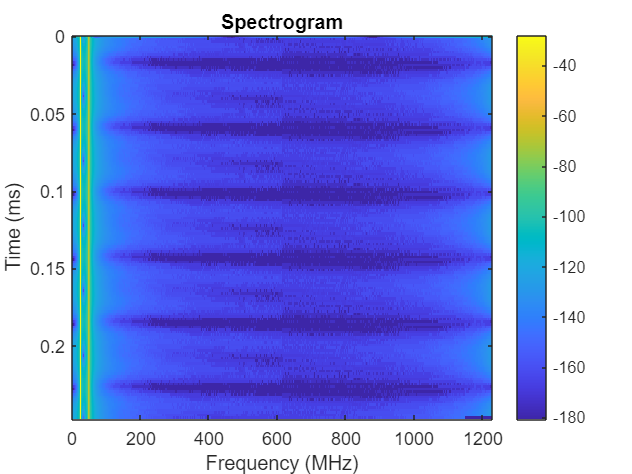


% Fill in the arrays to plot the spectrograms
for i=1:Num_Segments
    index = (i-1)*N+1 : i*N;
    t_axis(index) = t_axis_1N(i);
    Data(i,:) = fft_out_log(index);
    Data_(i,:) = fftshift(Data(i,:));
end

% Plot spectrograms 
figure;
imagesc(f_axis,t_axis,Data)
title('Spectrogram')
xlabel('Frequency (MHz)')
ylabel('Time (ms)')
colorbar

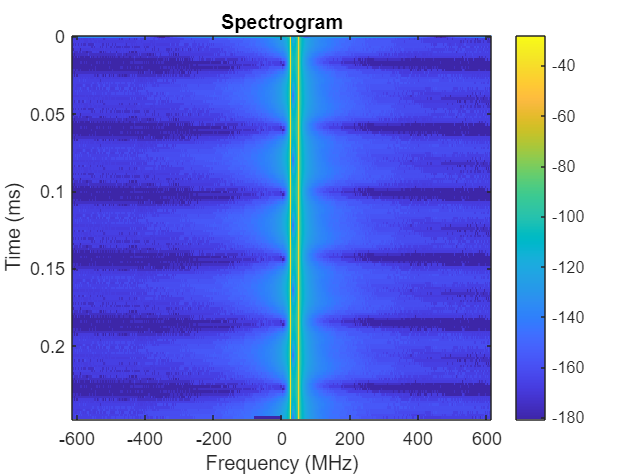

figure;
imagesc(f_axis_,t_axis,Data_)
title('Spectrogram')
xlabel('Frequency (MHz)')
ylabel('Time (ms)')
colorbar